# Q3. Creating Network - Image Classification *(40 points)*

## 1. Loading data (1)

***Data description**

Each image is 28 pixels in height and 28 pixels in width, for a total of 784 pixels in total. Each pixel has a single pixel-value associated with it, indicating the lightness or darkness of that pixel, with higher numbers meaning darker.

***Labels**

Each training and test example is assigned to one of the following labels:

- 0 T-shirt/top

- 1 Trouser

- 2 Pullover

- 3 Dress

- 4 Coat

- 5 Sandal

- 6 Shirt

- 7 Sneaker

- 8 Bag

- 9 Ankle boot

`q3_data.mat` stores labels and 28 x 28 gray images for train and test data. 

load q3_data.mat

## 2. Understanding data (7)

###     2.1. View the 1000th image in the train data and display its label (2)

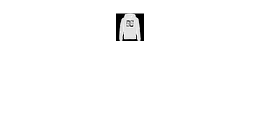

imshow(xTrain(:,:,:,1000))

yTrain(1000)

ans = categorical
     2 


###     2.2. Display the image size of the train data (1)

size(xTrain)

ans =           28          28           1        4000


###     2.3. How many images are class '4' in the train data (4)

## 3. Creating Network (6 points with no error)

Create a Convolutional Neural Network.

If you use Deep Network Designer App, **Be sure to ****name your network 'net_2' and include it into the zip file****, when you submit your answer.**

net2 = [imageInputLayer([28,28]);...
    convolution2dLayer([3,3],16);...
    reluLayer();
    convolution2dLayer([3,3],32);...
    reluLayer();
    maxPooling2dLayer([3,3]);
    fullyConnectedLayer(10);
    softmaxLayer();]

net2 =   다음 계층을 포함한 8×1 Layer 배열:

     1   ''   영상 입력          28×28×1 영상 (정규화: 'zerocenter')
     2   ''   2차원 컨벌루션      16개 3×3 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     3   ''   ReLU             ReLU
     4   ''   2차원 컨벌루션      32개 3×3 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     5   ''   ReLU             ReLU
     6   ''   2차원 최댓값 풀링   3×3 최댓값 풀링 (스트라이드: [1  1], 채우기: [0  0  0  0])
     7   ''   완전 연결          10 완전 연결 계층
     8   ''   소프트맥스         소프트맥스





% 18

## 4. Training Network (6)

Create appropriate training options and train the network. The training options you SHOULD KEEP are as follows.

- Max epochs $\le$ 50

- isplay training progress and accuracy for the training data

opts = trainingOptions("sgdm","MaxEpochs",50,"InitialLearnRate",0.001,...
    "Plots","training-progress","Metrics","accuracy","ExecutionEnvironment","auto","Shuffle","once")

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 50
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
             ObjectiveMetricName: 'loss'
                  CheckpointPath: '

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:00        0.001          2.2952              10.938
           50        2       00:00:05        0.001          1.9649              55.469
          100        4       00:00:08        0.001          1.0436              65.625
          150        5       00:00:11        0.001         0.75229              77.344
          200        7       00:00:13        0.001         0.57407               81.25
          250        9       00:00:16        0.001         0.67646              75.781
          300       10       00:00:18        0.001         0.58891              78.125
          350       12       00:00:21        0.001         0.55538              76.562
훈련이 중지됨: 수동으로 중지됨


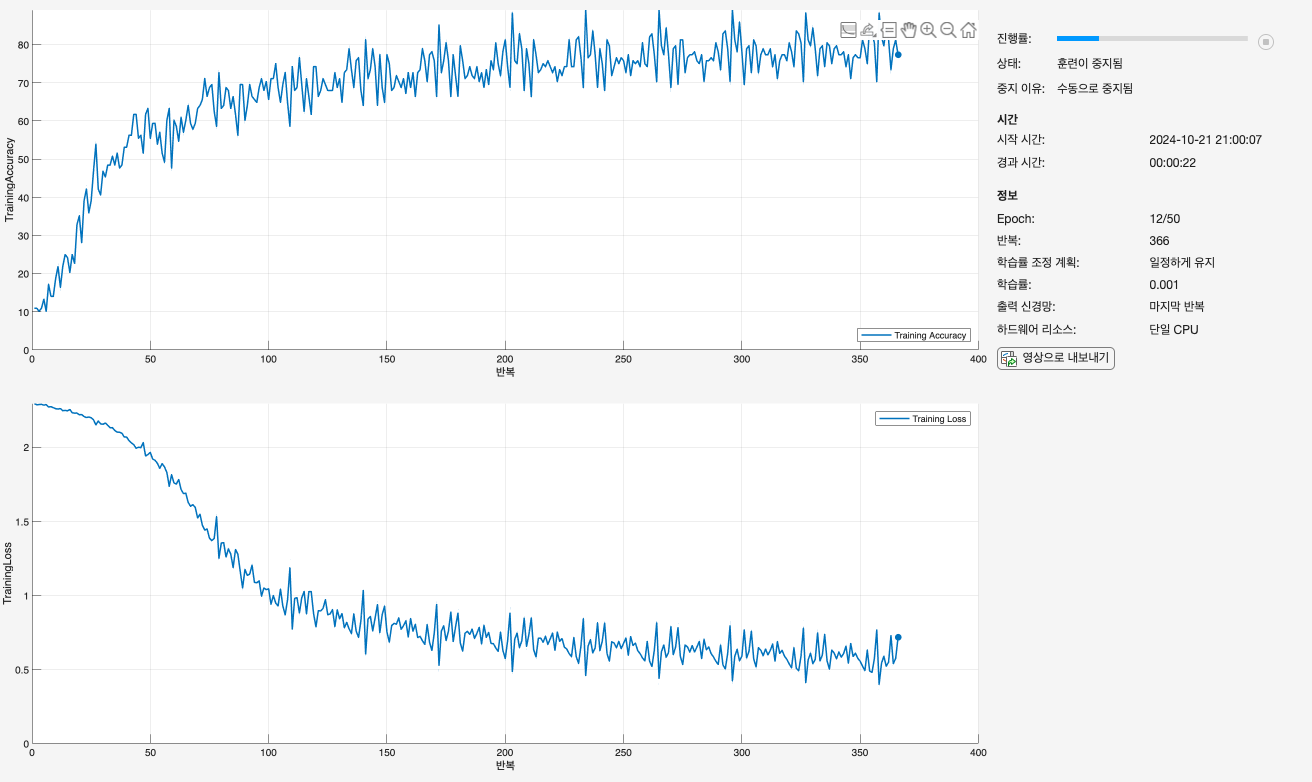

landnet =   dlnetwork - 속성 있음:

         Layers: [8×1 nnet.cnn.layer.Layer]
    Connections: [7×2 table]
     Learnables: [6×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  요약 보기(summary 참조).



landnet = trainnet(xTrain,yTrain,net2,"crossentropy",opts)








% 30

## 5. Evaluating Network (20)

Calculate the prediction accuracy on the test data. (When grading, your score will reflect the highest accuracy from five attempts.)

- Accuracy > 0.85             : 20 points

- 0.80 < Accuracy < 0.85  : 15 points

- Accuracy < 0.80             : 10 points

scores = minibatchpredict(landnet,xTrain)

scores = 4000×10 single 행렬
    0.5565    0.0064    0.0738    0.0255    0.0094    0.0169    0.3019    0.0010    0.0086    0.0001
    0.7779    0.0072    0.0244    0.0144    0.0030    0.0002    0.1716    0.0000    0.0012    0.0000
    0.9218    0.0007    0.0032    0.0037    0.0002    0.0000    0.0704    0.0000    0.0000    0.0000
    0.7499    0.0105    0.0184    0.0365    0.0034    0.0000    0.1810    0.0000    0.0002    0.0000
    0.5821    0.0032    0.0456    0.0210    0.0033    0.0005    0.3421    0.0002    0.0020    0.0002
    0.5594    0.0030    0.0181    0.0298    0.0071    0.0000    0.3826    0.0000    0.0001    0.0000
    0.4770    0.0188    0.1638    0.0149    0.0128    0.0005    0.3095    0.0000    0.0027    0.0000
    0.7698    0.0018    0.0103    0.0178    0.0007    0.0000    0.1996    0.0000    0.0001    0.0000
    0.2593    0.0274    0.0178    0.1465    0.1712    0.0000    0.3619    0.0001    0.0158    0.0000
    0.5548    0.0039    0.0938    0.0180    0.0045    0.0010    

classes = categorical(yTrain)

classes = 4000×1 categorical 배열
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


[testPred,score] = scores2label(scores,classes)

다음 사용 중 오류가 발생함: scores2label (10번 라인)
위치 2의 인수가 유효하지 않습니다. For categorical classes, the order of the values must match the order of the underlying categories. To check the underlying categories, use the categories function.

testGT = yTest
testAcc = nnz(testGT == testPred) / numel(testPred)
confusionchart(testGT,testPred)